# iEMG - Integrated EMG

iEMG is the sum of the absolute value of raw EMG data. We can think of it as the integral of the absolute value of our raw data. iEMG is used to determine a raise in signal power and amplitude.

[Mithbavkar, Shraddha Atul, and Milind Shantilal Shah. "Recognition of Emotion Through Facial Expressions Using EMG Signal." 2019 International Conference on Nascent Technologies in Engineering (ICNTE). IEEE, 2019.](https://drive.google.com/file/d/1z2df6YGj-S1I4xbYPOcqUqHkP70LQFSM/view?usp=sharing)

"When the absolute value of the signal is taken, noise will make the mathematical integral have a constant  increase."

[https://www.biopac.com/application/emg-electromyography/advanced-feature/automated-emg-analysis/](https://www.biopac.com/application/emg-electromyography/advanced-feature/automated-emg-analysis/) 

iEMG = sum(abs(data_ch1))

iEMG = 1×1000 single row vector
	1.0e+04 *

    4.3344    4.3322    4.3297    4.3204    4.2954    4.3342    4.3514    4.3419    4.3347    4.3682    4.3703    4.3382    4.3733    4.4032    4.3948    4.4036    4.3991    4.3837    4.4064    4.4179    4.4298    4.4260    4.4404    4.4620    4.4647    4.4904    4.4765    4.5101    4.5211    4.5229    4.4950    4.5051    4.5158    4.5206    4.5483    4.5579    4.5580    4.5594    4.5628    4.5699    4.5792    4.5910    4.5834    4.5769    4.5741    4.6167    4.6179    4.5834    4.6077    4.6065


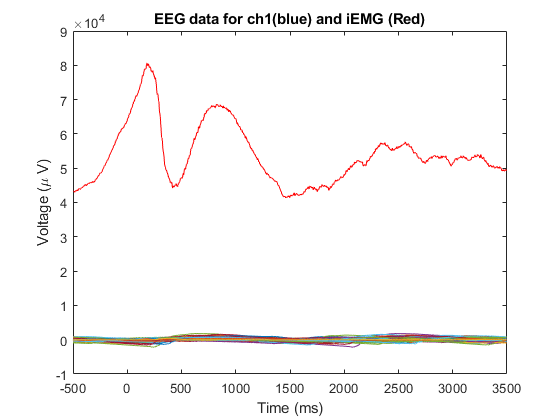

figure(1)
plot(times_ms, data_ch1) %...data from ch1
hold on
plot(times_ms,iEMG, 'r') %... iEMG performed on ch1 data
xlabel("Time (ms)")  %Label the x-axis as time.
ylabel("Voltage (\mu V)") %Label the y-axis as voltage.
title("EEG data for ch1(blue) and iEMG (Red)")
hold off %Release the current plot.